# OptForce

## Author: Sebastián N. Mendoza,  Center for Mathematical Modeling, University of Chile. snmendoz@uc.cl

## **Reviewers(s): Chiam Yu Ng (Costas D. Maranas group), **Lin Wang **(Costas D. Maranas group), John Sauls**

## **INTRODUCTION:**

In this tutorial we will run optForce. For a detailed description of the procedure, please see [1]. Briefly, the problem is to find a set of interventions of size "K" such that when these interventions are applied to a wild-type strain, the mutant created will produce a particular target of interest in a higher rate than the wild-type strain. The interventions could be knockouts (lead to zero the flux for a particular reaction), upregulations (increase the flux for a particular reaction) and downregulations (decrease the flux for a particular reaction). 

For example, imagine that we would like to increase the production of succinate in Escherichia coli. Which are the interventions needed to increase the production of succinate? We will approach this problem in this tutorial and we will see how each of the steps of OptForce are solved. 

## MATERIALS

## EQUIPMENT

- MATLAB

- A solver for Mixed Integer Linear Programming (MILP) problems. For example, Gurobi.

## **EQUIPMENT SETUP**

Use `changeCobraSolver` to choose the solver for MILP problems. 

## PROCEDURE

The proceduce consists on the following steps

1) Maximize specific growth rate and product formation.

2) Define constraints for both wild-type and mutant strain: 

3) Perform flux variability analysis for both wild-type and mutant strain.

4) Find must sets,  i.e, reactions that MUST increase or decrease their flux in order to achieve the phenotype in the mutant strain. 

## Figure 1.

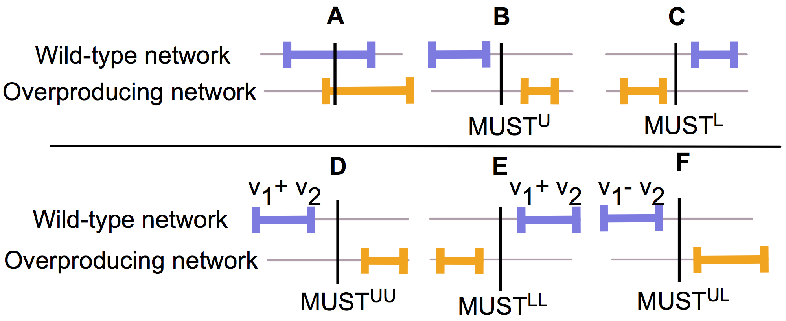

5) Find the interventions needed that will ensure a increased production of the target of interest

Now, we will approach each step in detail.

## STEP 1: Maximize specific growth rate and product formation

First, we load the model. This model comprises only 90 reactions, which describe the central metabolism of E. coli [2].

Then, we change the objective function to maximize biomass ("R75"). We also change the lower bounds, so E. coli will be able to consume glucose, oxygen, sulfate, ammomium, citrate and glycerol.

changeCobraSolver('gurobi', 'ALL');

***Local changes to submodules have been stashed. See https://git-scm.com/docs/git-stash.
Entering 'binary'
No local changes to save
Entering 'external/analysis/CnaCobraInterface'
No local changes to save
Entering 'external/analysis/GeoCalcLib'
No local changes to save
Entering 'external/analysis/PolytopeSamplerMatlab'
No local changes to save
Entering 'external/analysis/Volume-and-Sampling'
No local changes to save
Entering 'external/analysis/gaimc'
No local changes to save
Entering 'external/analysis/octave-networks-toolbox'
No local changes to save
Entering 'external/base/samplers/looplessFluxSampler'
No local changes to save
Entering 'external/base/solvers/lusol'
No local changes to save
Entering 'external/base/solvers/pdco'
No local changes to save
Entering 'external/base/utilities/Smith-Decomposition'
No local changes to save
Entering 'external/base/utilities/condalab'
No local changes to save
Entering 'papers'
No local changes to save
Entering 'test/models'
No local changes to s


 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2020a.
 > changeCobraSolver: Solver for LP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2020a.
 > changeCobraSolver: Solver for MILP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2020a.
 > changeCobraSolver: Solver for QP problems has been set to gurobi.

 > changeCobraSolver: Gurobi interface added to MATLAB path.
 > isCompatible: The solver compatibility cannot be verified with MATLAB R2020a.
 > changeCobraSolver: Solver for MIQP problems has been set to gurobi.
 > changeCobraSolver: Solver gurobi not supported for problems of type EP. No solver set for this problemtype 
 > changeCobraSolver: Solver gurobi n

modelFileName = 'iJO1366.mat';
modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded
model = readCbModel(modelFileName);

Each model.subSystems{x} is a character array, and this format is retained.


writeCbModel(model,'xls') 

Each model.subSystems{x} is a character array, and this format is retained.


%



model.c(strcmp(model.rxns, 'BIOMASS_Ec_iJO1366_core_53p95M')) = 1;
model = changeRxnBounds(model, 'EX_glc__D_e', -100, 'l'); 
model = changeRxnBounds(model, 'EX_o2_e', -100, 'l'); 
model = changeRxnBounds(model, 'EX_so4_e', -100, 'l'); 
model = changeRxnBounds(model, 'EX_nh4_e', -100, 'l'); 
model = changeRxnBounds(model, 'EX_cit_e', -100, 'l'); 
model = changeRxnBounds(model, 'EX_glyc_e', -100, 'l'); 


Then, we calculate the maximum specific growth rate and the maximum production rate for succinate.

growthRate = optimizeCbModel(model); 
fprintf('The maximum growth rate is %1.2f', growthRate.f);

The maximum growth rate is 9.26

model = changeObjective(model, 'EX_succ_e');
maxSucc = optimizeCbModel(model);
fprintf('The maximum production rate of succinate is %1.2f', maxSucc.f);

The maximum production rate of succinate is 400.00

**TIP: **The biomass reaction is usually set to 1%-10% of maximum theoretical biomass yield when running the following steps, to prevent solutions without biomass formation.

- Maximizing product formation

- Finding MUST sets of second order

- Finding FORCE sets

## STEP 2: Define constraints for both wild-type and mutant strain

**TIMING**: This step should take a few days or weeks, depending on the information available for your species. 

**CRITICAL STEP**: This is a manual task, so you should search for information in articles or even perform your own experiments. You can also make assumptions for describing the phenotypes of both strains which will make this task a little faster but make sure to have two strains different enough, because you should be able to find differences in reactions ranges. 

We define constraints for each strain as follows: 

- The WT strain's biomass function ("R75") is constrained to near the maximum growth rate. 

- The mutant strain's biomass function is set to zero. Succinate export ('EX_suc') is forced to be the maximum as calculated previously.

constrWT = struct('rxnList', {{'BIOMASS_Ec_iJO1366_core_53p95M'}}, 'rxnValues', 9, 'rxnBoundType', 'b')

constrWT = struct with fields:
         rxnList: {'BIOMASS_Ec_iJO1366_core_53p95M'}
       rxnValues: 9
    rxnBoundType: 'b'



constrMT = struct('rxnList', {{'BIOMASS_Ec_iJO1366_core_53p95M', 'EX_succ_e'}}, 'rxnValues', [0, 400.00], ...
                  'rxnBoundType', 'bb')

constrMT = struct with fields:
         rxnList: {'BIOMASS_Ec_iJO1366_core_53p95M'  'EX_succ_e'}
       rxnValues: [0 400]
    rxnBoundType: 'bb'


## Step 3: Flux Variability Analysis

**TIMING**: This task should take from a few seconds to a few hours depending on the size of your reconstruction

We  run the FVA analysis for both strains

[minFluxesW, maxFluxesW, minFluxesM, maxFluxesM, ~, ~] = FVAOptForce(model, ...
                                                                     constrWT, constrMT);
disp([minFluxesW, maxFluxesW, minFluxesM, maxFluxesM]);

   1.0e+03 *

         0         0         0         0
         0         0         0         0
   -0.1117    0.4880   -0.1212   -0.1000
   -0.0000   -0.0000         0         0
    0.0000    0.0000         0         0
    0.0000    0.0014         0         0
         0         0         0         0
    0.0000    0.0000         0         0
    0.0000    0.0361         0         0
         0    0.0014         0         0
         0    0.0028         0         0
   -0.1000   -0.0379   -0.1000   -0.1000
         0    0.0496         0         0
         0    0.0003         0         0
         0         0         0         0
         0    0.0005         0         0
         0         0         0         0
         0         0         0         0
    0.0090    0.0090         0         0
         0    0.0856         0         0
         0         0         0         0
         0         0         0         0
         0    0.0028         0         0
         0    0.0028         0         0
  

Now, the run the next step of OptForce.

## Step 4: Find Must Sets

**TIMING: **This task should take from a few seconds to a few hours depending on the size of your reconstruction

First, we define an ID for this run. Each time you run the functions associated to the optForce procedure, some folders can be generated to store inputs used in that run. Outputs are stored as well. These folders will be located inside the folder defined by your run ID. Thus, if your runID is ''TestOptForce", the structure of the folders will be the following:

`├── CurrentFolder`

`|   ├── TestOptForce`

`|   |   ├── Inputs`

`|   |   └── Outputs`

To avoid the generation of inputs and outputs folders, set `keepInputs = 0`, `printExcel = 0` and `printText = 0`.

Also, a report of the run is generated each time you run the functions associated to the optForce procedure. So, the idea is to give a different `runID` each time you run the functions, so you will be able to see the report (inputs used, outputs generated, errors in the run) for each run.

We define then our `runID`.

runID = 'OptForce_Suc_Ecoli';

Fow now, only functions to find first and second order must sets are supported in this third step. As depicted in **Figure 1**, the first order must sets are MUSTU and MUSTL; and second order must sets are MUSTUU, MUSTLL and MUSTUL.

**A) Finding first order must sets**

We define constraints.

constrOpt = struct('rxnList', {{'EX_glc__D_e', 'BIOMASS_Ec_iJO1366_core_53p95M', 'EX_succ_e'}}, 'values', [-100, 0, 400.00]');


We then run the functions `findMustL` and `findMustU` that will allow us to find `mustU` and `mustL` sets, respectively.

**i) MustL Set: **

[mustLSet, pos_mustL] = findMustL(model, minFluxesW, maxFluxesW, 'constrOpt', constrOpt, ...
                                  'runID', runID, 'outputFolder', 'OutputsFindMustL', ...
                                  'outputFileName', 'MustL' , 'printExcel', 1, 'printText', 1, ...
                                  'printReport', 1, 'keepInputs', 1, 'verbose', 0);

Note that the folder "TestOptForceM" was created. Inside this folder, two additional folders were created: "InputsMustL" and "OutputsMustL". In the inputs folder you will find all the inputs required to run the the function `findMustL`. Additionally, in the outputs folder you will find the `mustL` set found, which were saved in two files (.xls and .txt). Furthermore, a report which summarize all the inputs and outputs used during your running was generated. The name of the report will be in this format "report-Day-Month-Year-Hour-Minutes". So, you can mantain a chronological order of your experiments. 

We display the reactions that belongs to the `mustL` set.

disp(mustLSet)

    {'3OAR140' }
    {'3OAS140' }
    {'ACHBS'   }
    {'ACLS'    }
    {'AICART'  }
    {'ADSK'    }
    {'ASPCT'   }
    {'ASPK'    }
    {'ANPRT'   }
    {'ANS'     }
    {'ATPPRT'  }
    {'ATPS4rpp'}
    {'BPNT'    }
    {'CHORM'   }
    {'CHORS'   }
    {'CYSTL'   }
    {'DAPDC'   }
    {'DAPE'    }
    {'DDPA'    }
    {'DHAD1'   }
    {'DHAD2'   }
    {'DHDPRy'  }
    {'DHDPS'   }
    {'DHQS'    }
    {'DHQTi'   }
    {'FUM'     }
    {'GLNS'    }
    {'GLUPRT'  }
    {'HCO3E'   }
    {'HISTD'   }
    {'HISTP'   }
    {'HSK'     }
    {'HSST'    }
    {'HSTPT'   }
    {'IPMD'    }
    {'IPPS'    }
    {'KARA2'   }
    {'Ktex'    }
    {'IG3PS'   }
    {'IGPDH'   }
    {'IGPS'    }
    {'LEUTAi'  }
    {'METS'    }
    {'NH4tex'  }
    {'NH4tpp'  }
    {'MTHFR2'  }
    {'P5CR'    }
    {'O2tex'   }
    {'O2tpp'   }
    {'OMCDC'   }
    {'OMPDC'   }
    {'PGK'     }
    {'PItex'   }
    {'PPND'    }
    {'PPNDH'   }
    {'PRAGSr'  }
    {'PRAIS'   }
    {'PRAIi'   }
    {'PRAMPC' 

**ii) MustU set: **

[mustUSet, pos_mustU] = findMustU(model, minFluxesW, maxFluxesW, 'constrOpt', constrOpt, ...
                                  'runID', runID, 'outputFolder', 'OutputsFindMustU', ...
                                  'outputFileName', 'MustU' , 'printExcel', 1, 'printText', 1, ...
                                  'printReport', 1, 'keepInputs', 1, 'verbose', 0);

Note that the folders "InputsMustU" and "OutputsFindMustU" were created. These folders contain the inputs and outputs of `findMustU`, respectively. 

We display the reactions that belongs to the `mustU` set.

disp(mustUSet)

    {'EX_k_e'  }
    {'EX_nh4_e'}
    {'EX_pi_e' }
    {'EX_so4_e'}
    {'CO2tpp'  }
    {'DHORTS'  }
    {'ASAD'    }
    {'G3PD2'   }
    {'GAPD'    }
    {'IPPMIa'  }
    {'IPPMIb'  }
    {'KARA1'   }
    {'ILETA'   }
    {'IMPC'    }
    {'MALS'    }
    {'ORPT'    }
    {'PHETA1'  }
    {'SDPTA'   }
    {'TYRTA'   }



**B) Finding second order must sets **

First, we define the reactions that will be excluded from the analysis. It is suggested to include in this list the reactions found in the previous step as well as exchange reactions.

constrOpt = struct('rxnList', {{'EX_glc__D_e', 'BIOMASS_Ec_iJO1366_core_53p95M', 'EX_succ_e'}}, 'values', [-100, 0, 400.00]');
exchangeRxns = model.rxns(cellfun(@isempty, strfind(model.rxns, 'EX_')) == 0);
excludedRxns = unique([mustUSet; mustLSet; exchangeRxns]);

Now, we run the functions for finding second order must sets.

**i) MustUU: **

[mustUU, pos_mustUU, mustUU_linear, pos_mustUU_linear] = ...
    findMustUU(model, minFluxesW, maxFluxesW, 'constrOpt', constrOpt, ...
               'excludedRxns', excludedRxns,'runID', runID, ...
               'outputFolder', 'OutputsFindMustUU', 'outputFileName', 'MustUU', ...
               'printExcel', 1, 'printText', 1, 'printReport', 1, 'keepInputs', 1, ...
               'verbose', 1);

Set parameter Username
Set parameter TimeLimit to value 1e+36
Set parameter IntFeasTol to value 1e-09
Set parameter MIPGap to value 1e-12
Academic license - for non-commercial use only - expires 2023-07-05
Gurobi Optimizer version 9.5.1 build v9.5.1rc2 (win64)
Thread count: 18 physical cores, 36 logical processors, using up to 18 threads
Optimize a model with 24880 rows, 27638 columns and 88906 nonzeros
Model fingerprint: 0xc3288753
Variable types: 22472 continuous, 5166 integer (5166 binary)
Coefficient statistics:
  Matrix range     [2e-06, 2e+03]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-02, 1e+03]
  RHS range        [1e-02, 2e+03]
Presolve removed 11441 rows and 14387 columns
Presolve time: 0.33s
Presolved: 13439 rows, 13251 columns, 62321 nonzeros
Variable types: 10247 continuous, 3004 integer (3004 binary)

Root relaxation: infeasible, 6743 iterations, 0.82 seconds (1.21 work units)

    Nodes    |  

Note that the folders "InputsMustUU" and "OutputsFindMustUU" were created. These folders contain the inputs and outputs of `findMustUU`, respectively. 

We display the reactions that belongs to the` mustUU` set

disp(mustUU);


**ii) MustLL: **

[mustLL, pos_mustLL, mustLL_linear, pos_mustLL_linear] = ...
    findMustLL(model, minFluxesW, maxFluxesW, 'constrOpt', constrOpt, ...
               'excludedRxns', excludedRxns,'runID', runID, ...
               'outputFolder', 'OutputsFindMustLL', 'outputFileName', 'MustLL', ...
               'printExcel', 1, 'printText', 1, 'printReport', 1, 'keepInputs', 1, ...
               'verbose', 1);

Set parameter Username
Set parameter TimeLimit to value 1e+36
Set parameter IntFeasTol to value 1e-09
Set parameter MIPGap to value 1e-12
Academic license - for non-commercial use only - expires 2023-07-05
Gurobi Optimizer version 9.5.1 build v9.5.1rc2 (win64)
Thread count: 18 physical cores, 36 logical processors, using up to 18 threads
Optimize a model with 24880 rows, 27638 columns and 86874 nonzeros
Model fingerprint: 0x11ec052c
Variable types: 22472 continuous, 5166 integer (5166 binary)
Coefficient statistics:
  Matrix range     [2e-06, 2e+03]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-02, 1e+03]
  RHS range        [1e-02, 2e+03]
Presolve removed 11396 rows and 14374 columns
Presolve time: 0.26s
Presolved: 13484 rows, 13264 columns, 57238 nonzeros
Variable types: 10260 continuous, 3004 integer (3004 binary)

Root relaxation: objective 7.004160e-01, 6417 iterations, 0.82 seconds (1.18 work units)

    Nodes    |    Current Node    |     Objective Bounds      |     Wo

Note that the folders "InputsMustLL" and "OutputsFindMustLL" were created. These folders contain the inputs and outputs of `findMustLL`, respectively. 

We display the reactions that belongs to the `mustLL` set. In this case, `mustLL` is an empty array because no reaction was found in the `mustLL` set.

disp(mustLL);

**iii) MustUL: **

[mustUL, pos_mustUL, mustUL_linear, pos_mustUL_linear] = ...
    findMustUL(model, minFluxesW, maxFluxesW, 'constrOpt', constrOpt, ...
               'excludedRxns', excludedRxns,'runID', runID, ...
               'outputFolder', 'OutputsFindMustUL', 'outputFileName', 'MustUL', ...
               'printExcel', 1, 'printText', 1, 'printReport', 1, 'keepInputs', 1, ...
               'verbose', 1);

Note that the folders "InputsMustUL" and "OutputsFindMustUL" were created. These folders contain the inputs and outputs of `findMustUL`, respectively. 

We display the reactions that belongs to the `mustUL` set. In this case, `mustUL` is an empty array because no reaction was found in the `mustUL` set.

disp(mustUL);

**TROUBLESHOOTING 1: ** "I didn't find any reaction in my must sets"

**TROUBLESHOOTING 2: ** "I got an error when running the `findMustX` functions (X = L or U or LL or UL or UU depending on the case)"

## Step 5: OptForce

**TIMING: **This task should take from a few seconds to a few hours depending on the size of your reconstruction

We define constraints and we define `K` the number of interventions allowed, `nSets` the maximum number of sets to find, and `targetRxn` the reaction producing the metabolite of interest (in this case, succinate). 

Additionally, we define the `mustU` set as the union of the reactions that must be upregulated in both first and second order must sets; and `mustL` set as the union of the reactions that must be downregulated in both first and second order must sets .

%mustU = unique(union(mustUSet, mustUU));
%mustL = unique(union(mustLSet, mustLL));
mustU = mustUSet;
mustL = mustLSet;
targetRxn = 'EX_succ_e';
biomassRxn = 'BIOMASS_Ec_iJO1366_core_53p95M';
k = 1;
nSets = 1;
constrOpt = struct('rxnList', {{'EX_glc__D_e','BIOMASS_Ec_iJO1366_core_53p95M'}}, 'values', [-100, 0]);

[optForceSets, posOptForceSets, typeRegOptForceSets, flux_optForceSets] = ...
    optForce(model, targetRxn, biomassRxn, mustU, mustL, ...
             minFluxesW, maxFluxesW, minFluxesM, maxFluxesM, ...
             'k', k, 'nSets', nSets, 'constrOpt', constrOpt, ...
             'runID', runID, 'outputFolder', 'OutputsOptForce', ...
             'outputFileName', 'OptForce', 'printExcel', 1, 'printText', 1, ...
             'printReport', 1, 'keepInputs', 1, 'verbose', 1);

Set parameter Username
Set parameter TimeLimit to value 1e+36
Set parameter IntFeasTol to value 1e-09
Set parameter MIPGap to value 1e-12
Academic license - for non-commercial use only - expires 2023-07-05
Gurobi Optimizer version 9.5.1 build v9.5.1rc2 (win64)
Thread count: 18 physical cores, 36 logical processors, using up to 18 threads
Optimize a model with 58636 rows, 35385 columns and 178962 nonzeros
Model fingerprint: 0x02d78230
Variable types: 27636 continuous, 7749 integer (7749 binary)
Coefficient statistics:
  Matrix range     [2e-06, 1e+03]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-02, 1e+03]
  RHS range        [1e-02, 1e+03]
Presolve removed 38696 rows and 14439 columns
Presolve time: 0.32s
Presolved: 19940 rows, 20946 columns, 77296 nonzeros
Variable types: 18273 continuous, 2673 integer (2673 binary)
Found heuristic solution: objective -0.0000000

Root relaxation: objective 4.000000e+02, 7135 iterations, 0.82 seconds (1.36 work units)

    Nodes    |    Curr

ans = 1

Sets found by optForce were printed in OptForce.xls  
Sets found by optForce were printed in OptForce.txt  


Note that the folders "InputsOptForce" and "OutputsOptForce" were created. These folders contain the inputs and outputs of `optForce`, respectively.

We display the reactions found by `optForce`

disp(optForceSets)

    {'SUCCtex'}



The reaction found was "SUCt", i.e. a transporter for succinate (a very intuitive solution).

Next, we will increase `k` and we will exclude "SUCt" from upregulations to find non-intuitive solutions. 

**TIP: **Sometimes the product is at the end of a long linear pathway. In that case, the recomendation is to also exclude most reactions on the linear pathway. Essential reactions and reactions not associated with any gene (i.e. spontaneous reacitons) should also be excluded. 

We will only search for the 20 best solutions, but you can try with a higher number.

We will change the runID to save this second result (K = 2) in a diffetent folder than the previous result (K = 1) 

k = 1;
nSets = 20;
runID = 'TestOptForceM2';
excludedRxns = struct('rxnList', {{'SUCt'}}, 'typeReg','U');
[optForceSets, posOptForceSets, typeRegOptForceSets, flux_optForceSets] = ...
    optForce(model, targetRxn, biomassRxn, mustU, mustL, ...
             minFluxesW, maxFluxesW, minFluxesM, maxFluxesM, ...
             'k', k, 'nSets', nSets, 'constrOpt', constrOpt, ...
             'runID', runID, 'outputFolder', 'OutputsOptForce', ...
             'outputFileName', 'OptForce', 'printExcel', 1, 'printText', 1, ...
             'printReport', 1, 'keepInputs', 1, 'verbose', 1);

Set parameter Username
Set parameter TimeLimit to value 1e+36
Set parameter IntFeasTol to value 1e-09
Set parameter MIPGap to value 1e-12
Academic license - for non-commercial use only - expires 2023-07-05
Gurobi Optimizer version 9.5.1 build v9.5.1rc2 (win64)
Thread count: 18 physical cores, 36 logical processors, using up to 18 threads
Optimize a model with 58636 rows, 35385 columns and 178962 nonzeros
Model fingerprint: 0x02d78230
Variable types: 27636 continuous, 7749 integer (7749 binary)
Coefficient statistics:
  Matrix range     [2e-06, 1e+03]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e-02, 1e+03]
  RHS range        [1e-02, 1e+03]
Presolve removed 38696 rows and 14439 columns
Presolve time: 0.31s
Presolved: 19940 rows, 20946 columns, 77296 nonzeros
Variable types: 18273 continuous, 2673 integer (2673 binary)
Found heuristic solution: objective -0.0000000

Root relaxation: objective 4.000000e+02, 7135 iterations, 0.82 seconds (1.36 work units)

    Nodes    |    Curr

ans = 1

Sets found by optForce were printed in OptForce.xls  
Sets found by optForce were printed in OptForce.txt  


Note that the folders "InputsOptForce" and "OutputsOptForce" were created inside TestOptForce2. These folders contain the inputs and outputs of `optForce`, respectively.

We display the reactions found by `optForce` 

disp(optForceSets)

    {'SUCCtex' }
    {'O2tex'   }
    {'MALS'    }
    {'EX_k_e'  }
    {'EX_nh4_e'}
    {'EX_pi_e' }
    {'EX_so4_e'}
    {'CO2tpp'  }
    {'DHORTS'  }
    {'ASAD'    }
    {'ACONTa'  }
    {'G3PD2'   }
    {'GAPD'    }
    {'IPPMIa'  }
    {'IPPMIb'  }
    {'KARA1'   }
    {'ILETA'   }
    {'IMPC'    }
    {'SDPDS'   }
    {'ORPT'    }



## TIMING

- STEP 1 ~ 1-2 seconds

- STEP 2:  ~ 2-5 seconds

- STEP 3: ~ 10-20 seconds

- STEP 4: ~ 10-20 seconds

## TROUBLESHOOTING

1) Problem: "I didn't find any reaction in my must sets"

Possible reason: the wild-type or mutant strain is not constrained enough. 

Solution: add more constraints to your strains until you find differences in your reaction ranges. If you don't find any differences, it is better to change the approach and use another algorithm. 

2) Problem: "I got an error when running the `findMust` functions"

Possible reason: inputs are not defined well or solver is not defined.

Solution: verify your inputs, use `changeCobraSolver`, verify that the global variable `CBT_MILP_SOLVER` is not empty. It should containg the identifier for a MILP solver.

## ANTICIPATED RESULTS

In this tutorial some folders will be created inside the folder called "runID" to store inputs and outputs of the optForce functions (findMustU.m, findMustL.m, findMustUU.m, findMustLL.m, findMustUL.m, optForce.m)

In this case runID = 'TestOptForce', so inside this folder the following folders will be created:

`├── CurrentFolder`

`|   ├── TestOptForceM`

`|   |   ├── InputsFindMustL`

`|   |   ├── OutputsFindMustL`

`|   |   ├── InputsFindMustU`

`|   |   ├── OutputsFindMustU`

`|   |   ├── InputsFindMustLL`

`|   |   ├── OutputsFindMustLL`

`|   |   ├── InputsFindMustUU`

`|   |   ├── OutputsFindMustUU`

`|   |   ├── InputsFindMustUL`

`|   |   ├── OutputsFindMustUL`

`|   |   ├── InputsOptForce`

`|   |   └── OutputsOptForce`

The input folders contain inputs (.mat files) for running the functions to solve each one of the bilevel problems. Output folders contain results of the algorithms (.xls and .txt files) as well as a report (.txt) summarizing the outcomes of the steps performed during the execution of the optForce functions.

The optForce algorithm will find sets of reactions that should increase the production of your target. The first sets found should be the best ones because the production rate will be the highest. The last ones should be the worse because the production rete will be lower. Be aware that some sets could not guarante a minimum production rate for your target, so you always have to check the minimum production rate. You can do this using the function testOptForceSol.m. Some sets could allow a higher growth rate than others, so keep in mind this too when deciding which set is better.

## Acknowledgments

I would to thanks to the research group of Costas D. Maranas who provided the GAMS functions to solve this example. In particular I would like to thank to Chiam Yu Ng who kindly provides examples for using GAMS.

## References

[1] Ranganathan S, Suthers PF, Maranas CD (2010) OptForce: An Optimization Procedure for Identifying All Genetic Manipulations Leading to Targeted Overproductions. PLOS Computational Biology 6(4): e1000744. https://doi.org/10.1371/journal.pcbi.1000744.

[2] Maciek R. Antoniewicz, David F. Kraynie, Lisa A. Laffend, Joanna González-Lergier, Joanne K. Kelleher, Gregory Stephanopoulos, Metabolic flux analysis in a nonstationary system: Fed-batch fermentation of a high yielding strain of E. coli producing 1,3-propanediol, Metabolic Engineering, Volume 9, Issue 3, May 2007, Pages 277-292, ISSN 1096-7176, https://doi.org/10.1016/j.ymben.2007.01.003.